%% Problem 4: Low-pass and high-pass filtering effects on speech
clear; clc; close all;

% Robust input-file search for Live Script / temp execution paths.
fileName = 'mhint_01_01.wav';
labFixedDir = '/Users/hwy/Desktop/个人/26春/语音信号处理/lab1';

candidateDirs = {};
candidateDirs{end+1} = pwd;

try
    mPath = fileparts(mfilename('fullpath'));
    if ~isempty(mPath)
        candidateDirs{end+1} = mPath;
    end
catch
end

sPath = which('problem4_solution.m');
if ~isempty(sPath)
    candidateDirs{end+1} = fileparts(sPath);
end

candidateDirs{end+1} = labFixedDir;

inFile = '';
for i = 1:numel(candidateDirs)
    cFile = fullfile(candidateDirs{i}, fileName);
    if isfile(cFile)
        inFile = cFile;
        break;
    end
end

if isempty(inFile)
    error(['Cannot find ', fileName, '. Please set MATLAB Current Folder to:\n', ...
           labFixedDir]);
end

workDir = fileparts(inFile);
outDir = fullfile(workDir, 'problem4_outputs');
if ~exist(outDir, 'dir')
    mkdir(outDir);
end

fprintf('Using input file: %s\n', inFile);

Using input file: /Users/hwy/Desktop/个人/26春/语音信号处理/lab1/mhint_01_01.wav



[x, fs] = audioread(inFile);
if size(x, 2) > 1
    x = mean(x, 2);
end
x = x(:);

lpCuts = [1000, 750, 500, 400, 250];
hpCuts = [1000, 2000, 3000, 4000, 5000, 6000];
order = 4;
Nfft = 4096;

fprintf('Input fs = %d Hz, duration = %.3f s\n', fs, numel(x) / fs);

Input fs = 16000 Hz, duration = 3.729 s


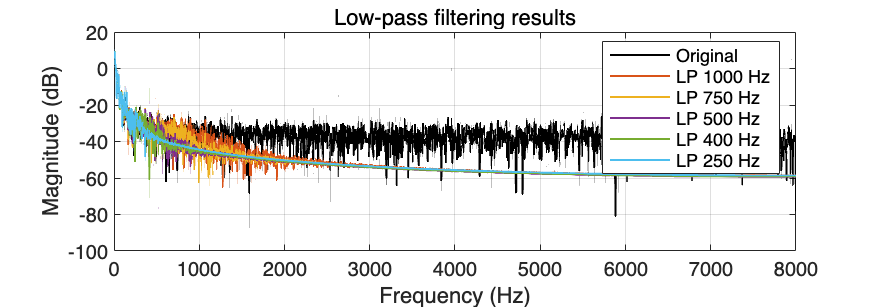


% Original spectrum
X = fft(x, Nfft);
fAxis = (0:Nfft/2) * fs / Nfft;
magOrig = 20 * log10(max(abs(X(1:Nfft/2+1)), 1e-10));

%% Low-pass processing
yLP = cell(size(lpCuts));
figure('Name', 'Problem 4 - Low-pass spectrum', 'Color', 'w', 'Position', [60 80 1200 420]);
plot(fAxis, magOrig, 'k', 'LineWidth', 1.0, 'DisplayName', 'Original'); hold on; grid on;

for i = 1:numel(lpCuts)
    fcut = lpCuts(i);
    Wn = fcut / (fs / 2);
    [b, a] = butter(order, Wn, 'low');
    yLP{i} = filter(b, a, x);

    outFile = fullfile(outDir, sprintf('mhint_lowpass_%dHz.wav', fcut));
    audiowrite(outFile, yLP{i}, fs);

    Y = fft(yLP{i}, Nfft);
    magY = 20 * log10(max(abs(Y(1:Nfft/2+1)), 1e-10));
    plot(fAxis, magY, 'LineWidth', 1.0, 'DisplayName', sprintf('LP %d Hz', fcut));
end
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Low-pass filtering results (cutoff markers shown)');
yl = ylim;
for i = 1:numel(lpCuts)
    xline(lpCuts(i), '--', 'Color', [0.55 0.55 0.55], 'LineWidth', 0.9, ...
        'HandleVisibility', 'off');
    text(lpCuts(i) + 20, yl(1) + 0.04 * (yl(2) - yl(1)), sprintf('f_c=%d', lpCuts(i)), ...
        'Color', [0.35 0.35 0.35], 'FontSize', 8, 'Rotation', 90, ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
end
legend('Location', 'northeast');
xlim([0 fs/2]);

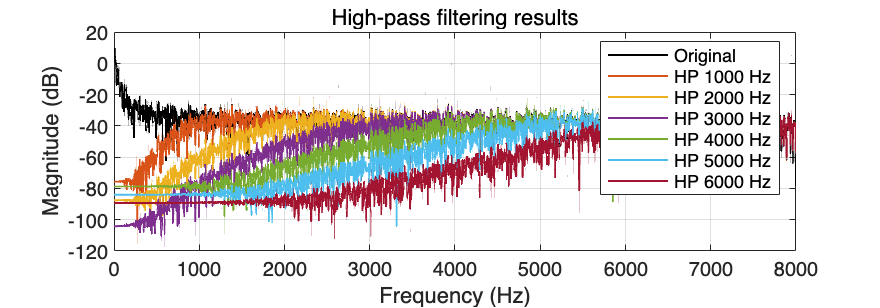


%% High-pass processing
yHP = cell(size(hpCuts));
figure('Name', 'Problem 4 - High-pass spectrum', 'Color', 'w', 'Position', [80 120 1200 420]);
plot(fAxis, magOrig, 'k', 'LineWidth', 1.0, 'DisplayName', 'Original'); hold on; grid on;

for i = 1:numel(hpCuts)
    fcut = hpCuts(i);
    Wn = fcut / (fs / 2);
    [b, a] = butter(order, Wn, 'high');
    yHP{i} = filter(b, a, x);

    outFile = fullfile(outDir, sprintf('mhint_highpass_%dHz.wav', fcut));
    audiowrite(outFile, yHP{i}, fs);

    Y = fft(yHP{i}, Nfft);
    magY = 20 * log10(max(abs(Y(1:Nfft/2+1)), 1e-10));
    plot(fAxis, magY, 'LineWidth', 1.0, 'DisplayName', sprintf('HP %d Hz', fcut));
end
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('High-pass filtering results (cutoff markers shown)');
yl = ylim;
for i = 1:numel(hpCuts)
    xline(hpCuts(i), '--', 'Color', [0.55 0.55 0.55], 'LineWidth', 0.9, ...
        'HandleVisibility', 'off');
    text(hpCuts(i) + 20, yl(1) + 0.04 * (yl(2) - yl(1)), sprintf('f_c=%d', hpCuts(i)), ...
        'Color', [0.35 0.35 0.35], 'FontSize', 8, 'Rotation', 90, ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
end
legend('Location', 'northeast');
xlim([0 fs/2]);


%% Listening/analysis guide
fprintf('\nFiltered wav files are saved to:\n%s\n', outDir);


Filtered wav files are saved to:
/Users/hwy/Desktop/个人/26春/语音信号处理/lab1/problem4_outputs


fprintf('\nSuggested listening commands in MATLAB:\n');


Suggested listening commands in MATLAB:


fprintf('  soundsc(yLP{1}, fs); %% low-pass example\n');

  soundsc(yLP{1}, fs); % low-pass example


fprintf('  soundsc(yHP{1}, fs); %% high-pass example\n');

  soundsc(yHP{1}, fs); % high-pass example



fprintf('\nReport writing tips (typical observations):\n');


Report writing tips (typical observations):


fprintf('1) Low-pass: as cutoff decreases, consonants become weaker and speech gets muffled.\n');

1) Low-pass: as cutoff decreases, consonants become weaker and speech gets muffled.


fprintf('2) High-pass: as cutoff increases, vowels lose energy and speech sounds thin/harsh.\n');

2) High-pass: as cutoff increases, vowels lose energy and speech sounds thin/harsh.


fprintf('3) Very low LP cutoff (<=400 Hz) or very high HP cutoff (>=4 kHz) greatly reduces intelligibility.\n');

3) Very low LP cutoff (<=400 Hz) or very high HP cutoff (>=4 kHz) greatly reduces intelligibility.



fprintf('\nProblem 4 done.\n');


Problem 4 done.


fprintf('Output directory: %s\n', outDir);

Output directory: /Users/hwy/Desktop/个人/26春/语音信号处理/lab1/problem4_outputs
